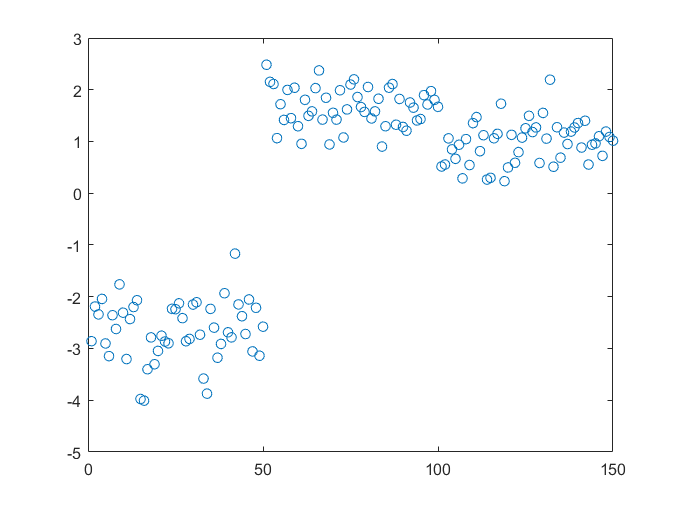

data = load('fisheriris.mat');
classA = data.meas(1:50,:);
classB = data.meas(51:150,:);
[ra,ca] = size(classA);
[rb,cb] = size(classB);
dat = [classA ones(ra,1);-classB -ones(rb,1)];
dat = zscore(dat);
t = [classA ones(ra,1);classB ones(rb,1)];
[r,c] = size(data.meas);
w = rand(c+1,1);
iter = 100;
outer= 0;
for j =1:iter
    outer= outer+1;
    w_temp = w;
    for i=1:r
        c1 = dat(i,:)*w;
        if c1<=0
            w = w + dat(i,:)';
        elseif c1>0
            continue
        end 
    end
    
    if(w == w_temp)
        break;
    end 
end
 
y = t*w;
% hold on
% scatter(data.meas(:,1),2*ones(150,1))
% scatter(y(1:50,:),ones(50,1),'red')
% scatter(y(51:150,:),ones(100,1),'yellow')
% g = [zeros(50,1);ones(100,1)];
y1 = dat*w;

plot(y1,'o');